% script to check the photon number linearity of a homodyne series measured
% with the Rotationstage Option

% load the data
MainDir = "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5";
d = dir(MainDir);
isub = [d(:).isdir]; %# returns logical vector
SeriesDir = {d(isub).name}';
SeriesDir(ismember(SeriesDir,{'.','..'})) = [];
SeriesDir = strcat(MainDir,filesep,SeriesDir)

SeriesDir = 21×1 string array
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.00"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.05"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.10"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.15"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.20"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.25"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.30"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.35"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.40"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.45"
    "D:\Data\Artifical DTS\18.12.2024\nCoherent_varied_nCoherent10_nThermal0.5\T0.50"
    "D:\Data\Artifical D

nSeries = length(SeriesDir);
nFiles = 10

nFiles = 10

[T,nTherm,nCoherent] = deal(zeros([nSeries,nFiles]));

for i = 1:nSeries
    disp(i)
    Files = QST.File_Managment.getFilePaths(SeriesDir(i));
    [~,~,Ext] = fileparts(Files);
    Files = Files(strcmp(Ext,".mat"));
    
    for j = 1:nFiles
        T(i,j) = QST.Variable_Managment.getMetaDataFromString(Files(j),"T[0-9]+[.]?[0-9]*","[0-9]+[.]?[0-9]*",[],@double);
        nTherm(i,j) = QST.Variable_Managment.getVariableFromFilePath(Files(j),["Wigner_5Sets_1Rho_500It.nTherm"]);
        nCoherent(i,j) = QST.Variable_Managment.getVariableFromFilePath(Files(j),["Wigner_5Sets_1Rho_500It.nCoherent"]);
    end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



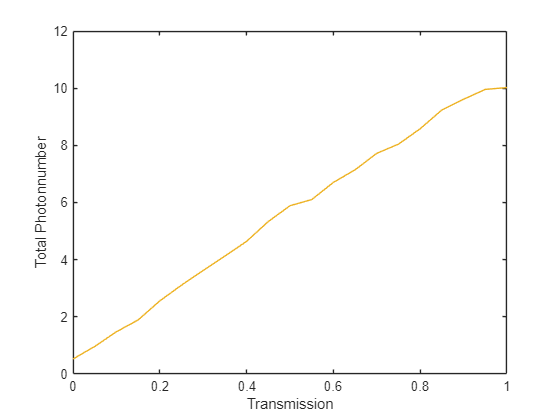

nTherm_Mean = mean(nTherm,2);
nCoherent_Mean = mean(nCoherent,2);
nTotal_Mean = nTherm_Mean + nCoherent_Mean;


% check linearity
plot(T,nTotal_Mean)
xlabel("Transmission");
ylabel("Total Photonnumber");

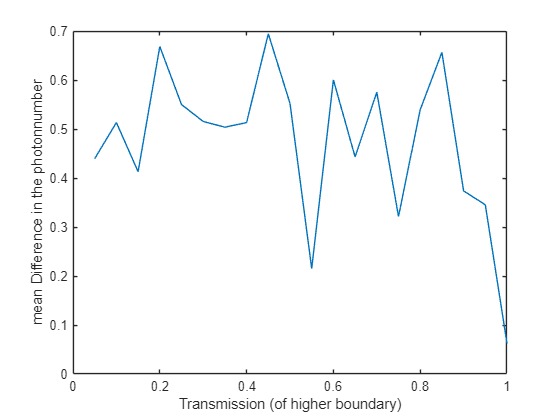

% -> seems to be more or less linear

% check if the steps are equidistant
Photondifferences = diff(nTotal_Mean);
plot(T(2:end,1),Photondifferences)
xlabel("Transmission (of higher boundary)");
ylabel("mean Difference in the photonnumber");

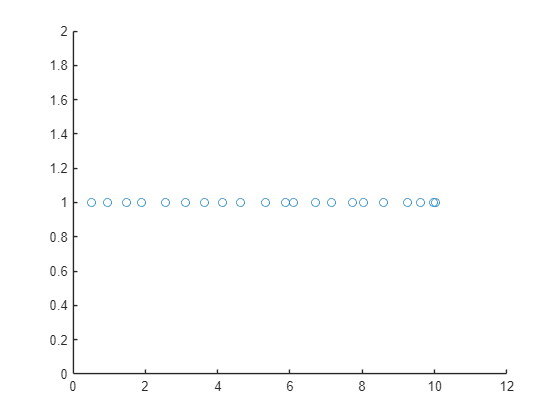

% the jumps are quite drastic between 0.1 and 0.3 -> this is not 
% equidistant

% different view on it
Constant = ones([1,nSeries]);
scatter(nTotal_Mean,Constant)